# `Demo_02:`    Steady State Heat Transfer Analysis **- Finite Element**

We will use the [**PDE Toolbox**](matlab:  web(fullfile(docroot, 'pde/index.html'))) to solve a 2D Thermal Analysis problem.

In this example we'll perform a **Steady State Thermal analysis** of a roof cavity insulation system typically found in residential houses.  The scenario that we'll consider is shown below:

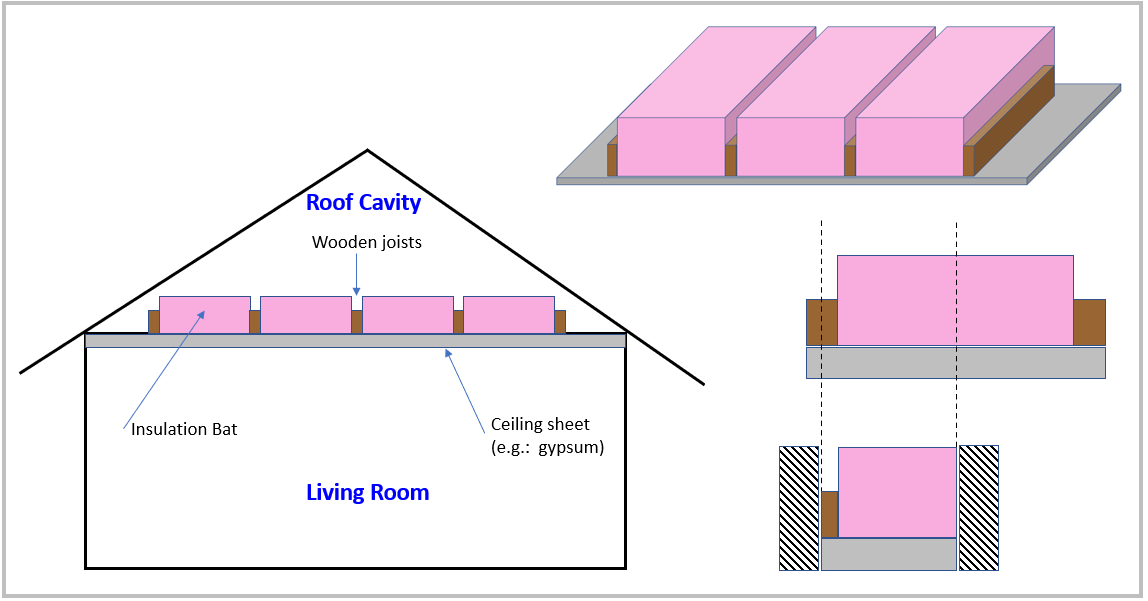

**History:**

- `19-Jul-2021: Created`

## Problem Description:

This script presents the Steady state thermal analysis of an insulation system installed in the roof cavity of a domestic house.  The system being considered is shown in the figure below - NOTE Point $\mathit{\mathbf{O}}$ is the "origin" for our spatial domain.  Key components of the system include:

- Component **A** :    a **Ceiling** sheet

- Component **B** :    a **Joist**

- Component **C** :    a Thermal insulation **Batt**

**System Boundary Conditions**

- Conduction in the X-direction through the EAST face of the  **Batt** is ZERO (a **symmetry condition**)

- Conduction in the X-direction through the WEST face of the  **Joist** is ZERO (a **symmetry condition**)

- Convection is possible in the Roof cavity (**Joist, Batt**)

- Convection is possible in the Living space (**Ceiling**)

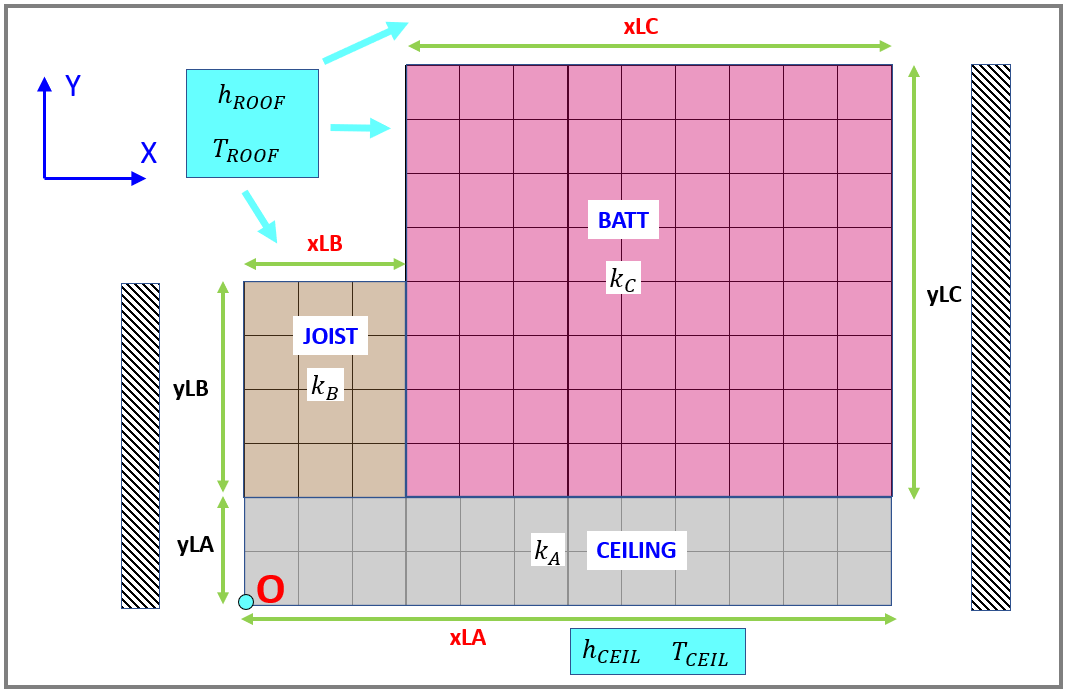

## **Load Thermal and Geometric parameters**

Thermal and geometry parameters for this system are defined in an EXCEL file [**bh_PARAMS_DATABASE.xlsx**](matlab: winopen(pwd  + string(filesep) + "bh_PARAMS_DATABASE.xlsx")).  So let's read this data in.

- **NOTE**:  The physical widths of the BATT and JOIST as expressed in the EXCEL file ... are halved when they are assigned to our geometry fields **xLB, xLC ...** because our thermal analysis applies symmetry boundary conditions at the joist and batt.

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1")

OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: []
         Nx_B: []
         Nx_C: []
         Ny_A: []
         Ny_B: []
         Ny_C: []
      Delta_X: []
      Delta_Y: []


## Some system dimensions:

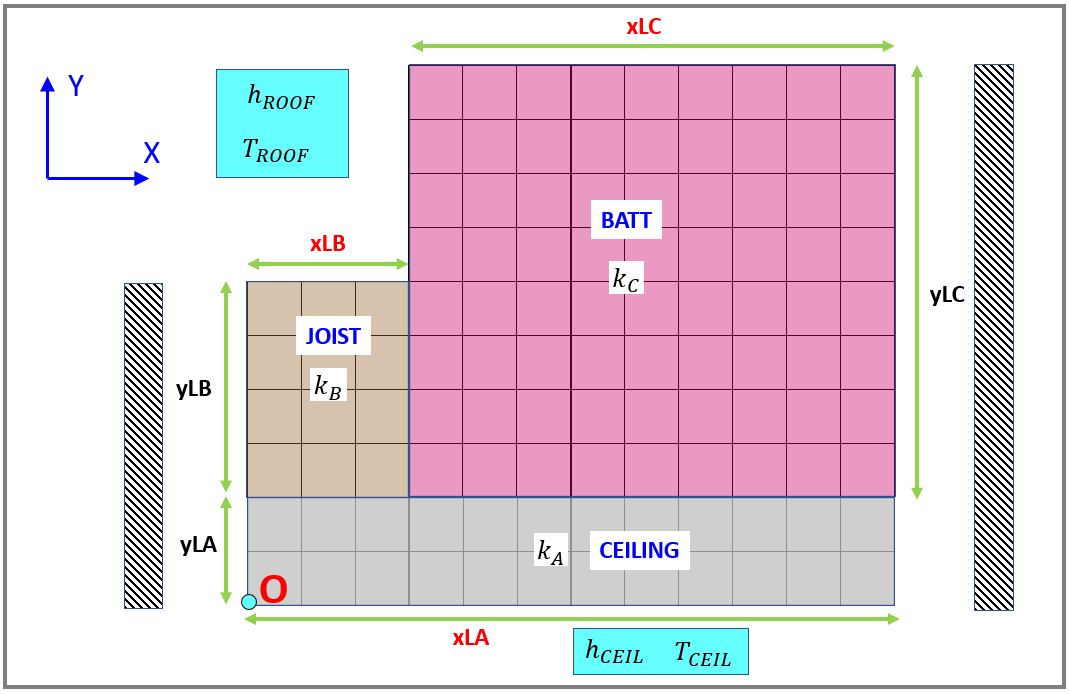

xLb = OBJ_params.xLB;  % (m)
xLc = OBJ_params.xLC;  % (m)

yLa = OBJ_params.yLA;  % (m)
yLb = OBJ_params.yLB;  % (m)
yLc = OBJ_params.yLC;  % (m) 

## **Create a Steady State Thermal model**

Use the [**createpde**](matlab:  web(fullfile(docroot, 'pde/ug/createpde.html'))) function to define the type of problem that we want to solve:

thermalmodel = createpde('thermal','steadystate');

## **Define the geometry of our 3 "blocks"**

We'll use the [`decsg`](matlab:  doc decsg)() function and the [`geometryFromEdges`](matlab:  doc geometryFromEdges)() function to define the geometry of our components, ie:

- $\textrm{R1A}:$ will be our **gypsum** rectangle

- $\textrm{R2B}:$ will be our **joist** rectangle

- $\textrm{R3C}:$ will be our **batt** rectangle

The DOC page for [`decsg`](matlab:  doc decsg)() defines the format for specifying this geometry.  Eg: For a rectangle, 

- The first row contains 3, and the second row contains 4. 

- The next four rows contain the x-coordinates of the starting points of the edges, and the four rows after that contain the y-coordinates of the starting points of the edges.

R1A_gdm_gyp_COL  = [3 4   0      (xLb+xLc)   (xLb+xLc)      0 ...
                          0      0           yLa            yLa     ]';

R2B_gdm_joi_COL  = [3 4   0       xLb         xLb          0 ...
                          yLa     yLa        (yLa+yLb)    (yLa+yLb) ]';

R3C_gdm_bat_COL  = [3 4   xLb    (xLb+xLc)   (xLb+xLc)     xLb  ...
                          yLa     yLa        (yLa+yLc)    (yLa+yLc) ]';

Now use the  [`decsg`](matlab:  doc decsg) function

ns  = ['R1A'; 'R2B'; 'R3C']'; 
gdm = [R1A_gdm_gyp_COL, R2B_gdm_joi_COL, R3C_gdm_bat_COL];

g   = decsg(gdm,'R1A + R2B + R3C',ns);

Thsi geometry gets "absorbed" into our thermal model by using the  [`geometryFromEdges`](matlab:  doc geometryFromEdges)() function:

geometryFromEdges(thermalmodel,g);

## Visualize the geometry

We can visualize the 3 regions(or components) using the [`pdegplot`](matlab:  web(fullfile(docroot, 'pde/ug/pdegplot.html'))) function:

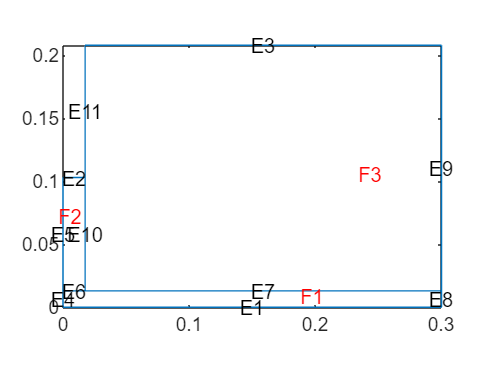

figure;
    pdegplot(thermalmodel,'EdgeLabels','on','SubdomainLabels','on')
        axis equal

## Setup the boundary conditions

The plot produced by [`pdegplot`](matlab:  web(fullfile(docroot, 'pde/ug/pdegplot.html'))) shows the labels for the **FACES** (F) and **EDGES** (E) for our 3 components.  We'll now configure our system boundary conditions using these labels AND the [`thermalBC`](matlab: web(fullfile(docroot, 'pde/ug/pde.thermalmodel.thermalbc.html'))) function

% EDGE 1:  boundary with INDOOR living space
thermalBC(thermalmodel,'Edge',1,'ConvectionCoefficient',OBJ_params.h_CEIL, 'AmbientTemperature',OBJ_params.T_CEIL);

% EDGE 2,3,11:  boundary with ROOF cavity space
thermalBC(thermalmodel,'Edge',2, 'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);
thermalBC(thermalmodel,'Edge',3, 'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);
thermalBC(thermalmodel,'Edge',11,'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);

% EDGE 9: is our BATT symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',9,'HeatFlux',0);
% EDGE 8: is our GYPSUM symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',8,'HeatFlux',0);

% EDGE 5: is our JOIST symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',5,'HeatFlux',0);
% EDGE 4: is our GYPSUM symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',4,'HeatFlux',0);

## Specify Thermal Properties of the Materials

Specify the thermal conductivity of the material.

-      
$$k\;\;\left\lbrack \frac{W}{m\ldotp K}\right\rbrack$$
   

thermalProperties(thermalmodel, 'Face', 3, 'ThermalConductivity', OBJ_params.k_C); % BATTS
thermalProperties(thermalmodel, 'Face', 2, 'ThermalConductivity', OBJ_params.k_B); % JOISTS
thermalProperties(thermalmodel, 'Face', 1, 'ThermalConductivity', OBJ_params.k_A); % GYPSUM

## Generate the mesh

Now generate the Finite Element mesh using the function [`generateMesh`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.generatemesh.html')))

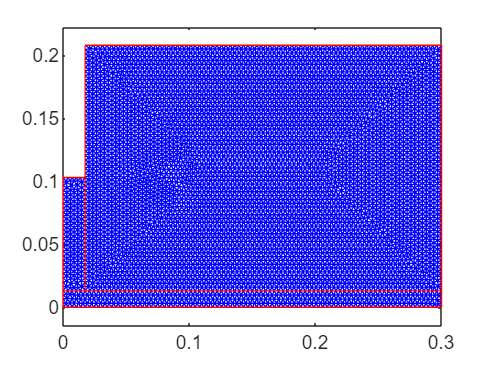

generateMesh(thermalmodel, 'Hmax', xLb/5);

figure
    pdeplot(thermalmodel)

## Calculate Solution

Use the [`solve`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.solve.html'))) function to calculate the solution.

- NOTE:  the returned result will be a [`SteadyStateThermalResults`](matlab:  web(fullfile(docroot, 'pde/ug/pde.steadystatethermalresults.html'))) object

thermalresults = solve(thermalmodel)

thermalresults =   SteadyStateThermalResults with properties:

    Temperature: [23089×1 double]
     XGradients: [23089×1 double]
     YGradients: [23089×1 double]
     ZGradients: []
           Mesh: [1×1 FEMesh]


## Visualize the solution:

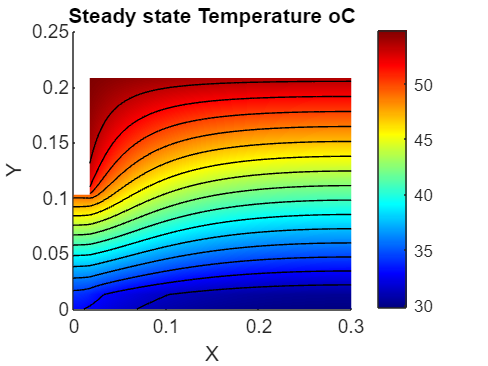

figure;
    pdeplot(thermalmodel,'XYData',thermalresults.Temperature,'ColorMap','jet', ...
        "Contour","on", "Levels", 15);
    %pdeplot(thermalmodel,'XYData',thermalresults.Temperature,'ZData',thermalresults.Temperature,'ColorMap','jet');
        xlabel('X');
        ylabel('Y');
        title('Steady state Temperature oC')

## Explore a SLICE of our solution

y_tgt  = 0.042;
x_list = linspace(0, (xLb + xLc), 200);
y_list = y_tgt * ones(size(x_list));

Tintrp = interpolateTemperature(thermalresults, x_list, y_list);

mean_T = mean(Tintrp, 'omitnan')

mean_T = 35.2567

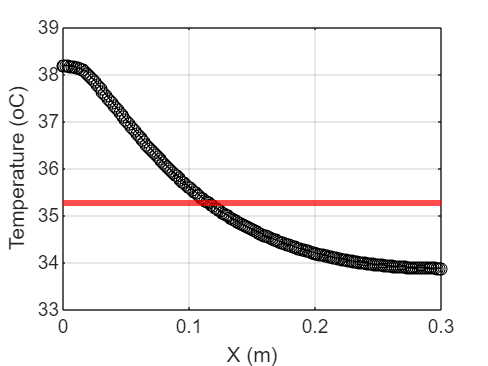


figure;
    plot(x_list, Tintrp, '-ko');
        xlabel('X (m)');
        ylabel('Temperature (oC)');
        grid('on')
    hold('on')
    yline(mean_T, '-r', 'LineWidth',3)

## Now compute the Heat flow rate flowing through the ceiling boundary

We can use the [`evaluateHeatRate`](matlab:  web(fullfile(docroot, 'pde/ug/pde.steadystatethermalresults.evaluateheatrate.html'))) function to compute the integrated heat flow rate normal to a specified boundary:

Qn = evaluateHeatRate(thermalresults,'Edge',1)  

Qn = 2.2108